# Mobility framework

## Rigid Quadruped

We refer back to our previous work: [Geometric Mechanics of Nonslip Contact in a Planar Quadruped](https://arxiv.org/abs/2308.14357), where using a single level-set around the origin of the continuous shape subspace decoupled through shared stance, we tuned subgaits to achieve complicated average locomotion control and steering through a two-beat trot gait.

Here, using the mobility framework and discrete CCFs/stratified panels, we want to show that gait controllability is guaranteed.

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
hamr6_F = false;
switch hamr6_F
    case true
        dataName = 'Data\HAMR6_SE2_kinematics.mat';
        dataMotPlanName = 'Data\HAMR6_SE2_kinematics_motionplan.mat';
        dataMobility = 'Data\HAMR6_SE2_kinematicMobility.mat';
    case false
        dataName = 'Data\case_1_kinematics.mat';
        dataMotPlanName = 'Data\case_1_kinematics_motionplan.mat';
        dataMobility = 'Data\case_1_kinematicMobility.mat';
end
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
if exist(dataName, "file")
    load(dataName);
else
    error(['ERROR! The base kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx".']);
end
if exist(dataMotPlanName, "file")
    load(dataMotPlanName);
else
    error(['ERROR! The motion planning kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx" (last section).']);
end

### Slip-nonslip coordinates

#### Generation

We package the tools from the previous discussion into a 'Path2_mobility' class.

Creating instances of 'Path2_mobility' to compute the slip and nonslip coordinates at two stance phase of a trot gait-cycle.

submanifoldIndex = 5; % we know that FR-HL stance phase is 5
integrationTime = 1.2*ones(1, 2); % set to paper 2 params for uniformity
refPtOrg = zeros(1, 2); % choose the reference point about which to compute
                        % the slip and nonslip directions
                        % ... we defaultly choose the orgin to first
                        % ... replicate our results from Paper 2.
FRHLstance = Path2_Mobility(submanifoldIndex, ...
                    kin, kinfunc, p_kin, p_info, ...
                    integrationTime, refPtOrg); % compute current stance

We identify the complementary submanifold using a static method in the "Path2_Mobility" class and then automatically construct and return that object.

FLHRstance = Path2_Mobility.constructComplementaryStance...
                    (FRHLstance, ...
                    kin, kinfunc, p_kin, p_info, ...
                    integrationTime, refPtOrg); % compute complementary stance

Save the stance phase data.

% if exist(dataMobility, "file")
%     save(dataMobility, "FRHLstance", "FLHRstance", "-append");
% else
%     save(dataMobility, "FRHLstance", "FLHRstance");
% end

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
hamr6_F = false;
switch hamr6_F
    case true
        dataName = 'Data\HAMR6_SE2_kinematics.mat';
        dataMotPlanName = 'Data\HAMR6_SE2_kinematics_motionplan.mat';
        dataMobility = 'Data\HAMR6_SE2_kinematicMobility.mat';
    case false
        dataName = 'Data\case_1_kinematics.mat';
        dataMotPlanName = 'Data\case_1_kinematics_motionplan.mat';
        dataMobility = 'Data\case_1_kinematicMobility.mat';
end
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
if exist(dataName, "file")
    load(dataName);
else
    error(['ERROR! The base kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx".']);
end
if exist(dataMotPlanName, "file")
    load(dataMotPlanName);
else
    error(['ERROR! The motion planning kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx" (last section).']);
end
if exist(dataMobility, "file")
    load(dataMobility);
else
    error(['ERROR! The mobility kinematics data file is needed. ' ...
        'Create one in the previous section.']);
end

#### Visualization

Let's plot this new coordinates for the two contact states in a trot gait.

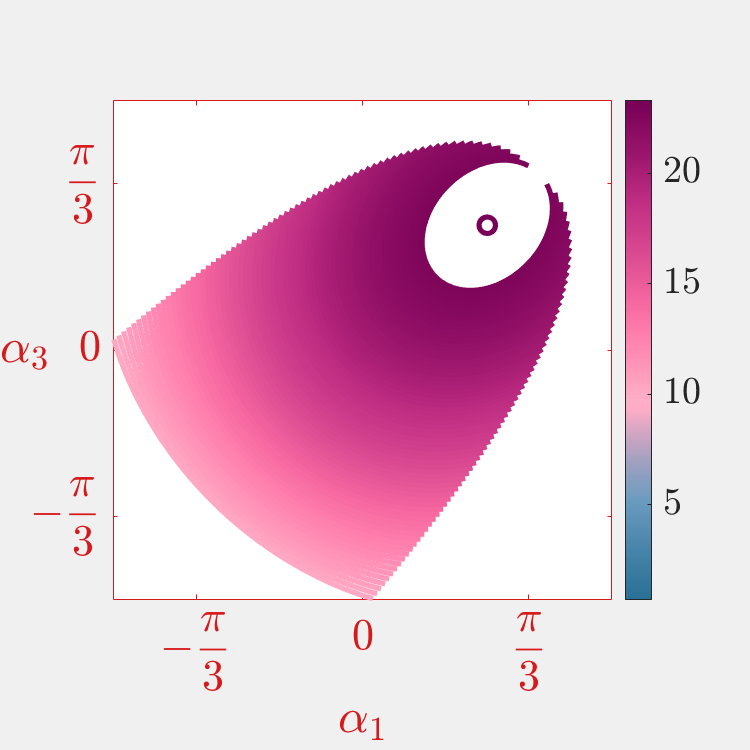

Path2_Mobility.visualizeNonslipLevelSets(FRHLstance)

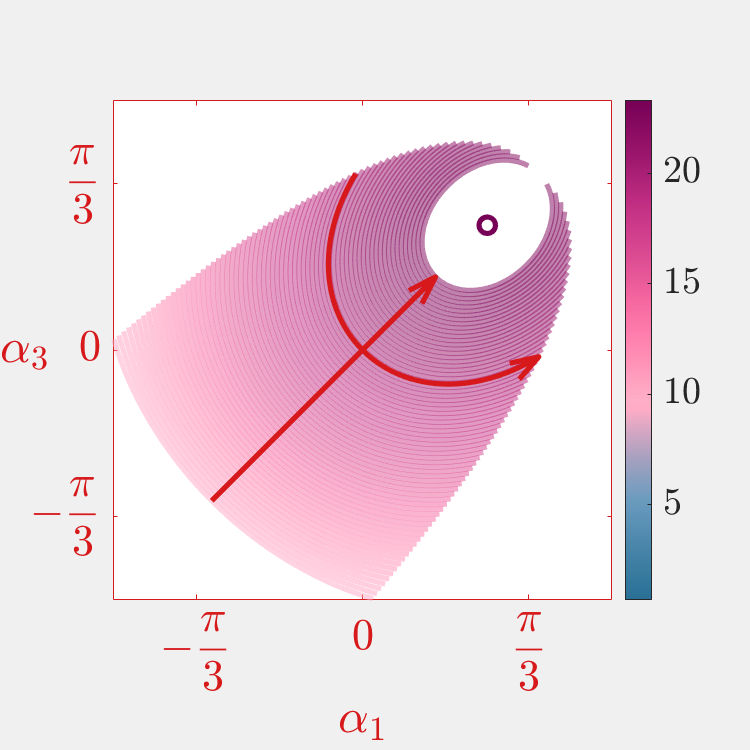

Path2_Mobility.visualizeSlipNonslipShapeCoordinates(FRHLstance)

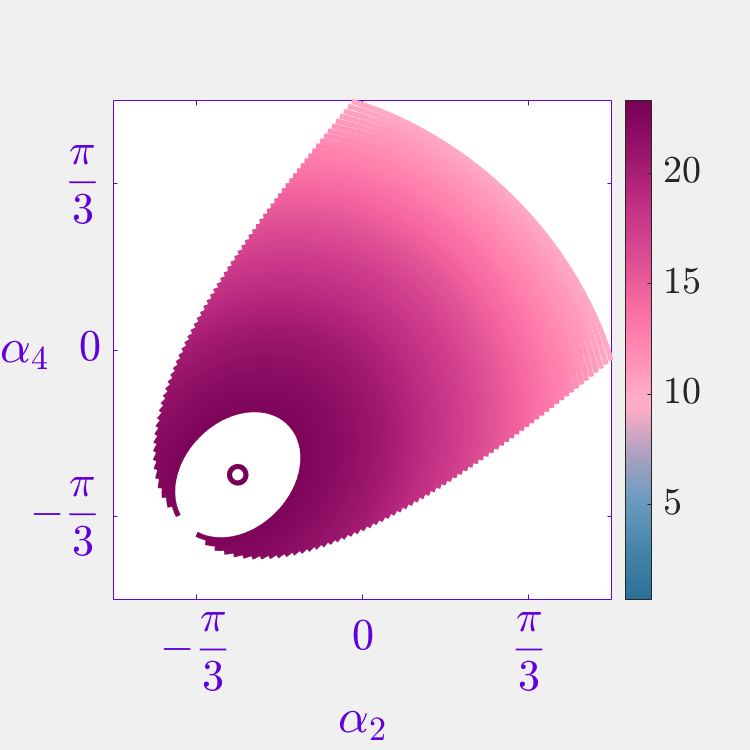

Path2_Mobility.visualizeNonslipLevelSets(FLHRstance)

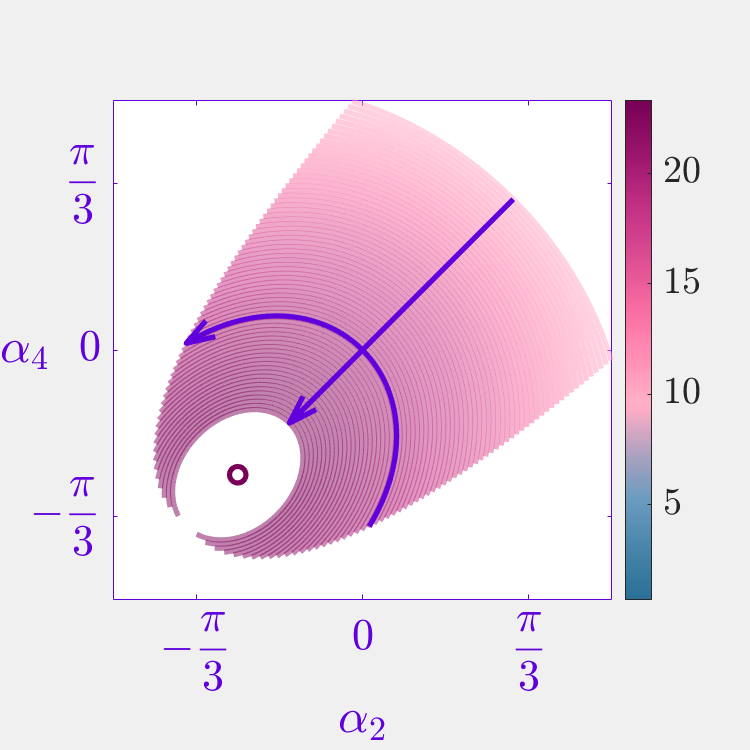

Path2_Mobility.visualizeSlipNonslipShapeCoordinates(FLHRstance)

Let's highlight the reference paths at $[0,0]$ where we shall carry out our mobility analysis.

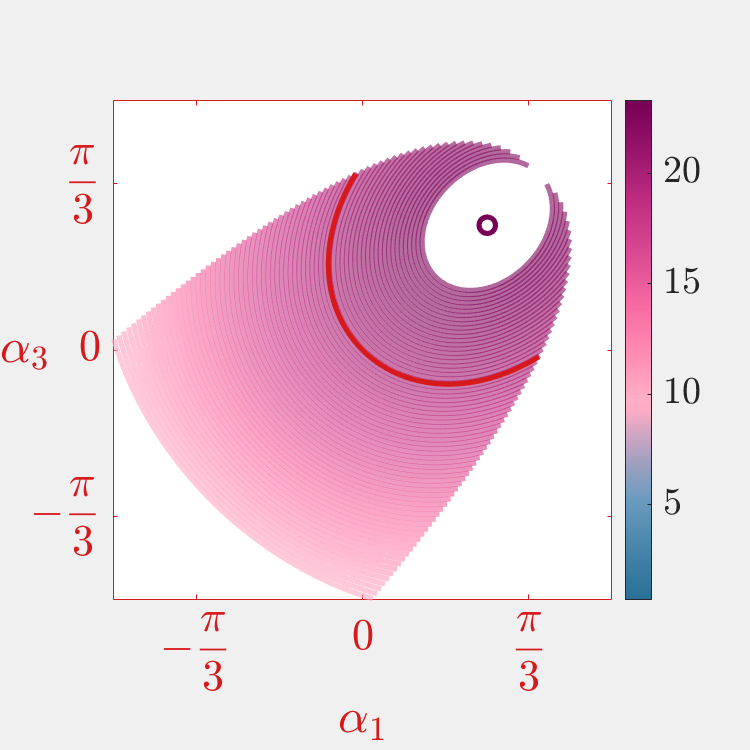

Path2_Mobility.highlightNonslipLevelSet(FRHLstance, zeros(1, 2))

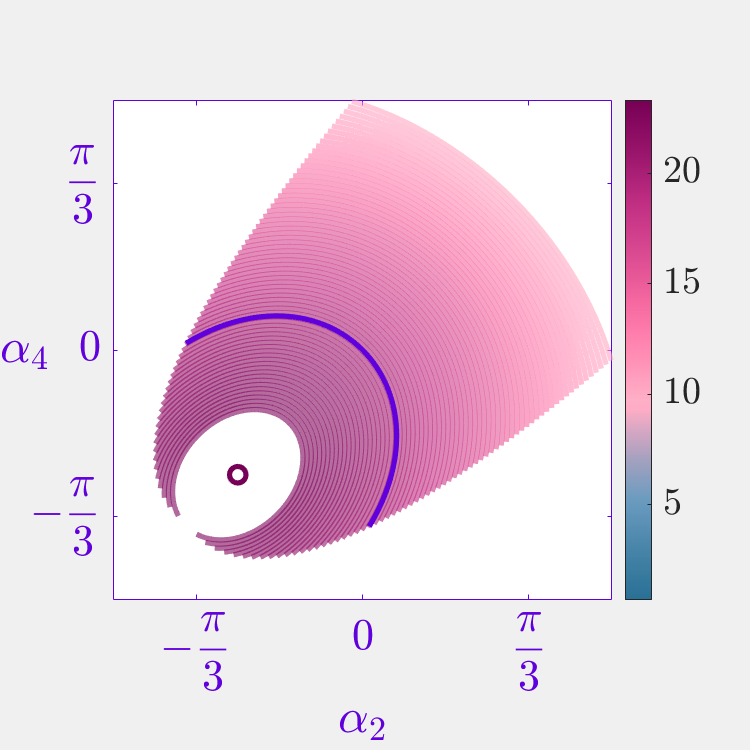

Path2_Mobility.highlightNonslipLevelSet(FLHRstance, zeros(1, 2))

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
hamr6_F = false;
switch hamr6_F
    case true
        dataName = 'Data\HAMR6_SE2_kinematics.mat';
        dataMotPlanName = 'Data\HAMR6_SE2_kinematics_motionplan.mat';
        dataMobility = 'Data\HAMR6_SE2_kinematicMobility.mat';
    case false
        dataName = 'Data\case_1_kinematics.mat';
        dataMotPlanName = 'Data\case_1_kinematics_motionplan.mat';
        dataMobility = 'Data\case_1_kinematicMobility.mat';
end
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
if exist(dataName, "file")
    load(dataName);
else
    error(['ERROR! The base kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx".']);
end
if exist(dataMotPlanName, "file")
    load(dataMotPlanName);
else
    error(['ERROR! The motion planning kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx" (last section).']);
end
if exist(dataMobility, "file")
    load(dataMobility);
else
    error(['ERROR! The mobility kinematics data file is needed. ' ...
        'Create one in the first section of this livescript.']);
end

### Noncommutative approximation of net-displacement

The goal is to not completely simulate the system for every combination of scaling and sliding inputs (for inputs, references, and parameters displayed in ["Geometrically Modulable Gait Design for Quadrupeds"](https://doi.org/10.1109/LRA.2024.3418311)) at different level-sets, and as the body parameter changes because it computationally expensive and doesn't allow us to quickly iterate over designs and gait-schedules.

In this section, we explore the requirements for approximating the net displacement obtained sequential stance paths arising from two-beat gaits. This would require combining the flows along the lie-algebra elements into one flow-- thus we use the BCH series to approximate the noncommutativity arising from such a choice. We first construct an trotting instance of the alternating quadrupedal gait class, "altQuadGait", using the "Path2_Mobility" class instances we generated earlier for pairs of diagonal legs that stance together.

% valid leaf mode arguments: "origin-only"
% valid input mode arguments: {"std", "path_limit_compliant"}
% ... if the input mode is "path_limit_compliant", we need integration
% ... limits; an example is commented at the end of the line below
rigidTrot = altQuadGait(FRHLstance, FLHRstance, "origin-only", "std") % , [-2, 2]

rigidTrot =   altQuadGait with properties:

              ithStance: [1×1 Path2_Mobility]
              jthStance: [1×1 Path2_Mobility]
    leafExplorationMode: "origin-only"
              inputMode: 'std'
      integrationLimits: [-Inf Inf]
            stanceSpace: [1×1 struct]


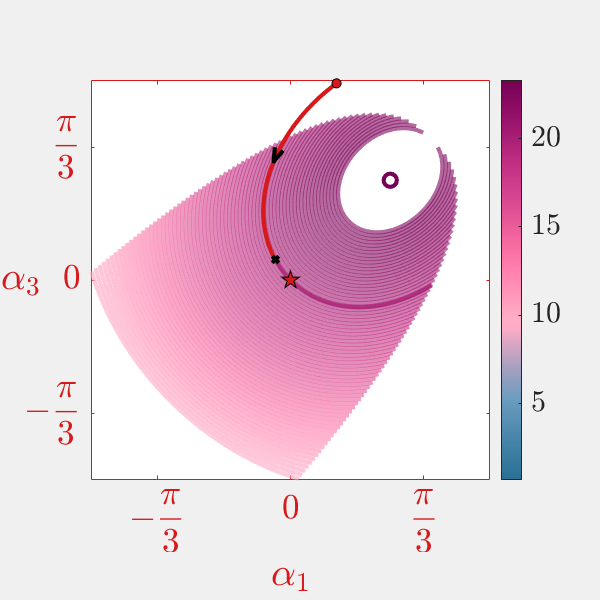

% ... switch input modes using this method:
% thisAltGait = alternatingQuadrupedalGait.switchInputMode(thisAltGait, "path_limit_compliant", [-2, 2]);
ref = []; 
ref.P = zeros(1, 2); ref.T = -0.8*ones(1, 2); % reference point and integration times to generate stance paths
% ... ... select trajectories from paper 2
% inputs = [+1.0, +0.0, +1.0, +0.0]; % traj 4, 9
% inputs = [+1.0, +0.5, +1.0, -0.5]; % traj 7
% inputs = [-1.0, +0.0, +1.0, +0.0]; % traj 10, 15
inputs = [-1.0, -1.0, +1.0, +1.0]; % traj 12
% ... ... 
ref13 = ref; ref24 = ref;
[ref13.tOff, ref13.tMax, FRHLstance] = Path2_Mobility.computeToffFromPerpCoord(ref.P, FRHLstance);
[ref24.tOff, ref24.tMax, FLHRstance] = Path2_Mobility.computeToffFromPerpCoord(ref.P, FLHRstance);
[tIC, tFC] = altQuadGait.computeGaitIntegrationTimes(    rigidTrot, ... % gait instance
                                                         inputs, ... % scaling and sliding inputs concatenated
                                                         [ref13.T,    ref24.T], ... % integration times
                                                         [ref13.tOff, ref24.tOff], ... % offset times
                                                         [ref13.tMax, ref24.tMax]   ); % max integration times
% ... final flag plots subgaits in shape subspace
configTraj13 = Path2_Mobility.simulateConfigurationTrajectory...
                                                    (ref13, ...
                                                     [tIC(1), tFC(1)], ...
                                                     FRHLstance, true);

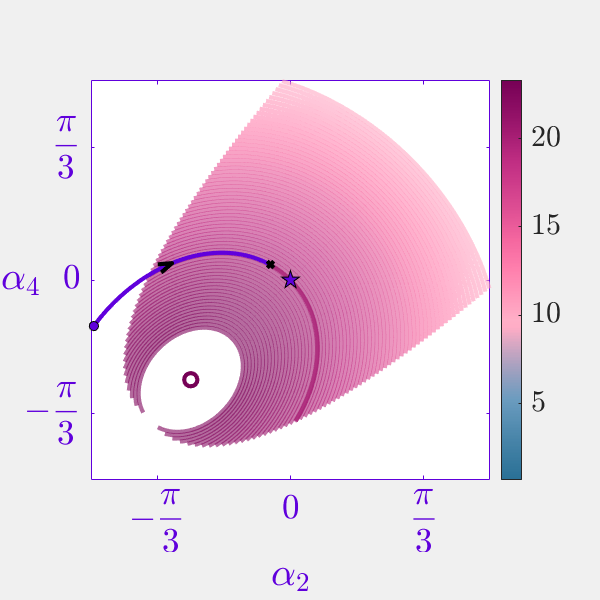

configTraj24 = Path2_Mobility.simulateConfigurationTrajectory...
                                                    (ref24, ...
                                                     [tIC(2), tFC(2)], ...
                                                     FLHRstance, true);

We need several different levels of body trajectory, more essentially **the net displacement approximation** from the individual stance trajectories we computed earlier. More details on these approximations are listed below in the order of compute:

- First, we use the exponentiated individual stance trajectories obtained using the local commutativity assumption and stitch them from front to back making it a **piecewise commutative approximation**.

- From this case, we assume the flows are happening simultaneously along the two lie-algebra elements from each stance phase. This will be a **joint, commutative approximation**.

- We add the second order term from the BCH expansion and make our first **joint, noncommutative approximation**.

- 3rd order added

- 4th order added

We are computing both the "complete" and "discretized" cases because for smaller scaling inputs, we believe the "discretized" case would provide coarser approximations under quicker compute times.

Let's visualize the body trajectory with the different levels of the lie-bracket estimates to analyze convergence and pickout the best and lowest order estimate. First we make a normal plot, then in the second one we zoom in and pick out the true differences in the net displacements.

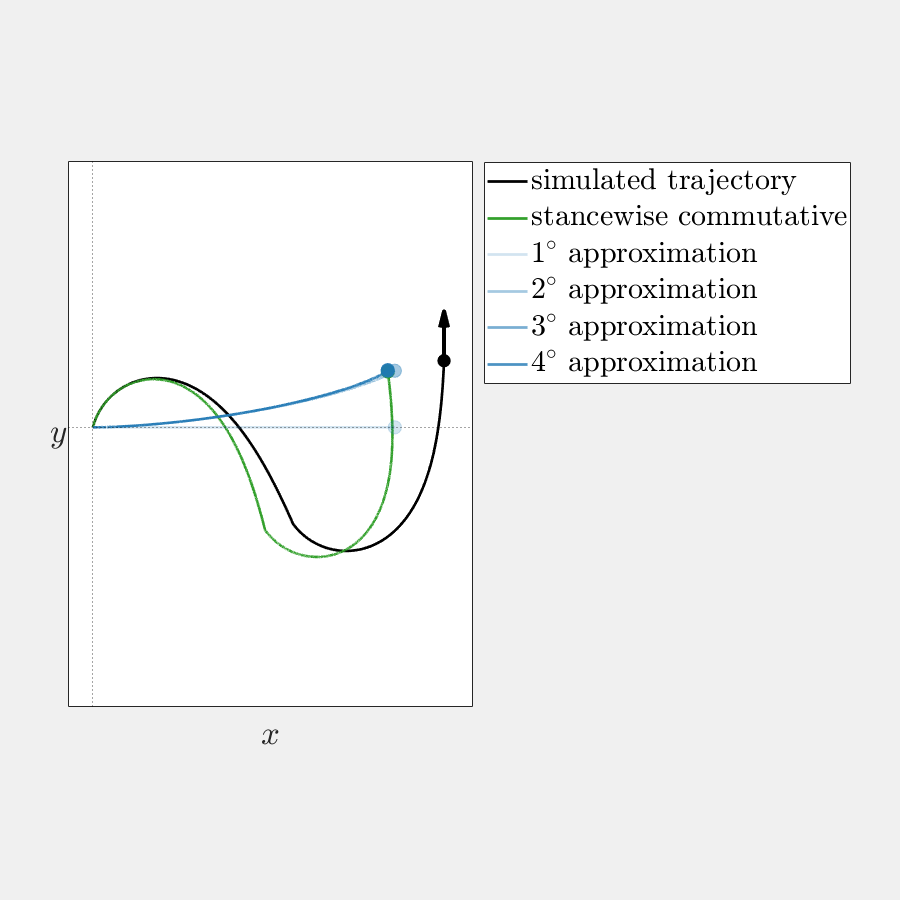

% obtain the complete configuration trajectory
% ... the second last argument is the maximum BCH expansion order needed to
% ... approximate the body trajectory; current it only supports order 4.
% ... --if it is zero, then only the simulated trajectory and stanceiwse
% ... commutative plots are presented
% ... --if the approximation order is left empty, then just the simulated
% ... trajectory is plotted
% ...
% ... the last binary arguments presence plots the body trajectory and its
% ... approximations and if true, repeats the plot without text so that we
% ... can zoom in obtain the differences between the estimates
jointStancePath = altQuadGait.fullCycleConfigTrajectory(rigidTrot, configTraj13, configTraj24, 4, false);

Also, plot the simulated trajectory as a timeseries.

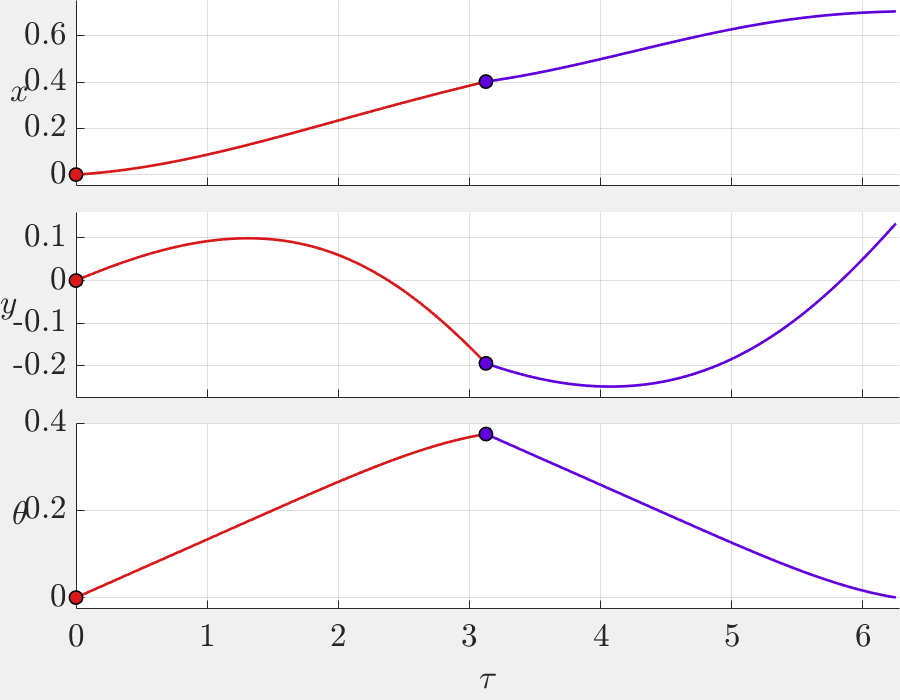

pltMode = 'stance_colored'; % options: 'stance_colored', 'k'
scatterFlag = true; % scatter dots at the beginning of each stance phase change % has use only during the 'stance_colored'
altQuadGait.plotBodyTimeseries(rigidTrot, configTraj13, configTraj24, pltMode, scatterFlag);

Save the results before plotting the trajectories.

if exist(dataMobility, "file")
    save(...
        dataMobility, ...
    "ref13", "ref24", "inputs", ...
    "FRHLstance", "FLHRstance", ...
    "configTraj13", "configTraj24", ...
    "rigidTrot", "jointStancePath", ...
    "-append"...
        );
else
    error(['ERROR! The mobility kinematics data file is needed. ' ...
        'Create one in the first section of this livescript.']);
end

While we use the complete trajectory information and discretized trajectory information in this example case, moving forward, we shall use lookup tables to obtain a much better estimate on how many time steps to have based on the path length. This lookup table is computed and stored as a property in the constructor. And, for exploring more global properties like the gait reachable set (of robot positions), we shall only need displacement point-clouds.

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
hamr6_F = false;
switch hamr6_F
    case true
        dataName = 'Data\HAMR6_SE2_kinematics.mat';
        dataMotPlanName = 'Data\HAMR6_SE2_kinematics_motionplan.mat';
        dataMobility = 'Data\HAMR6_SE2_kinematicMobility.mat';
    case false
        dataName = 'Data\case_1_kinematics.mat';
        dataMotPlanName = 'Data\case_1_kinematics_motionplan.mat';
        dataMobility = 'Data\case_1_kinematicMobility.mat';
end
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
if exist(dataName, "file")
    load(dataName);
else
    error(['ERROR! The base kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx".']);
end
if exist(dataMotPlanName, "file")
    load(dataMotPlanName);
else
    error(['ERROR! The motion planning kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx" (last section).']);
end
if exist(dataMobility, "file")
    load(dataMobility);
else
    error(['ERROR! The mobility kinematics data file is needed. ' ...
        'Create one in the first section of this livescript.']);
end

### Obtaining gait-plans

Next, we intend the visualize the subgait trajectories as a function of time. For this, we explicity compute them during stance phase, reverse the obtained trajectory (and condition the discretization) for the swing phase. The setup is very similar to the last section. More specifically, the 'Path2_Mobility' class method 'computeSubgaitInCoordinates' is very similar to the 'simulateConfigurationTrajectory' method. All of this is packaged into the method, "obtainGaitFSapproximation", in the new alternating quadrupedal gait class, "altQuadGait".

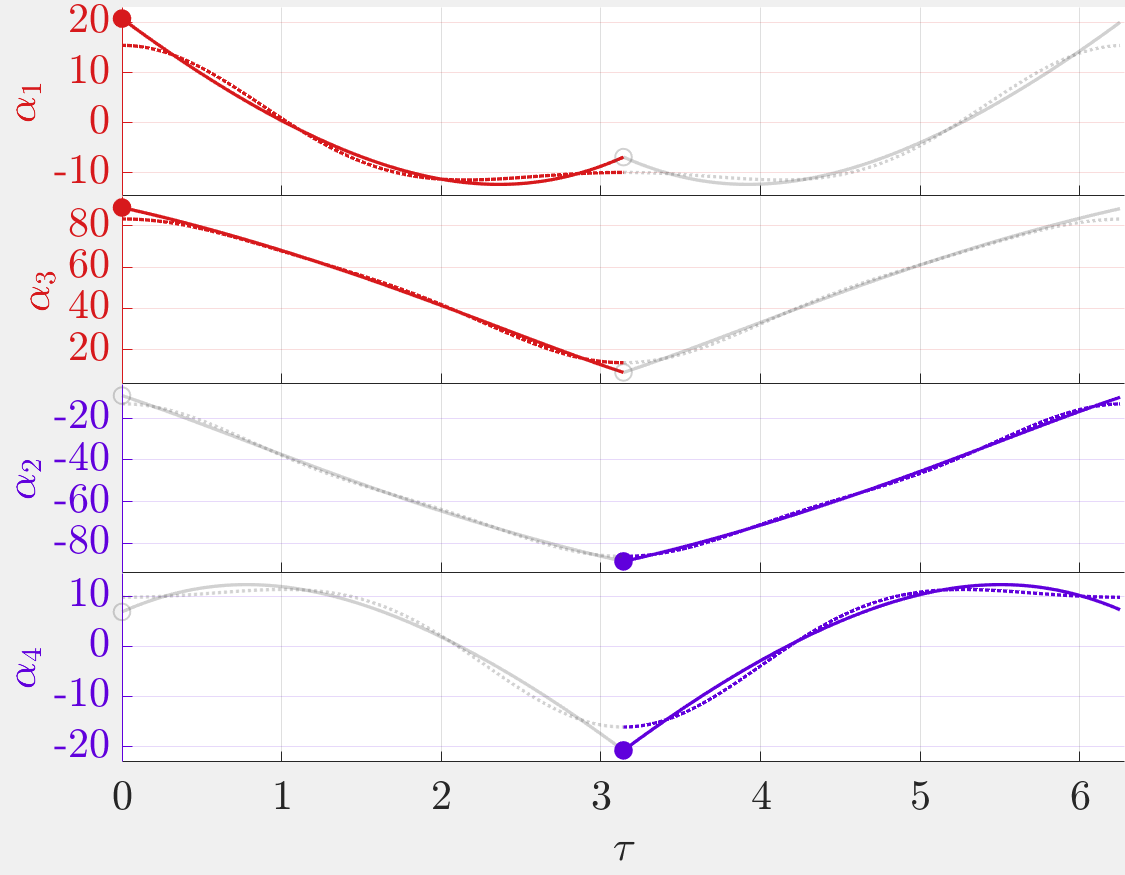

% definition of the references
% ... this can be changed by following the properties defined in the
% ... "Path2_Mobility" class for the instances 'FRHLstance' and
% ... 'FLHRstance' which correspond to limbs 13 and 24 respectively
ref = []; 
ref.P = zeros(1, 2); ref.T = -0.8*ones(1, 2);
% ... ... select trajectories from paper 2
% inputs = [+1.0, +0.0, +1.0, +0.0]; % traj 4, 9
% inputs = [+1.0, +0.5, +1.0, -0.5]; % traj 7
% inputs = [-1.0, +0.0, +1.0, +0.0]; % traj 10, 15
inputs = [-1.0, -1.0, +1.0, +1.0]; % traj 12
% set the each reference
ref13 = ref; ref24 = ref;
% obtain the fourier series approximation for the current reference and
% inputs
% ... the approximation order is 3 because currently that's the upper-limit
% ... of our embedded firmware-hardware capabilities
% ... keeping the plot structure (second last input) to 
% ... flag:'true' and mode:'stance_colored'
% ... keeping the .csv exporter of the FS coefficients flag to 'false'
pltStruct = []; 
    pltStruct.flag = true; 
        pltStruct.mode = 'stance_colored'; % options: 'stance_colored', 'k'
genCSVflag = false;
[pFS, subGT, subGTFS] = ...
                    altQuadGait.obtainGaitFSapproximation...
                        (rigidTrot, ref13, ref24, inputs, ...
                                3, pltStruct, genCSVflag);

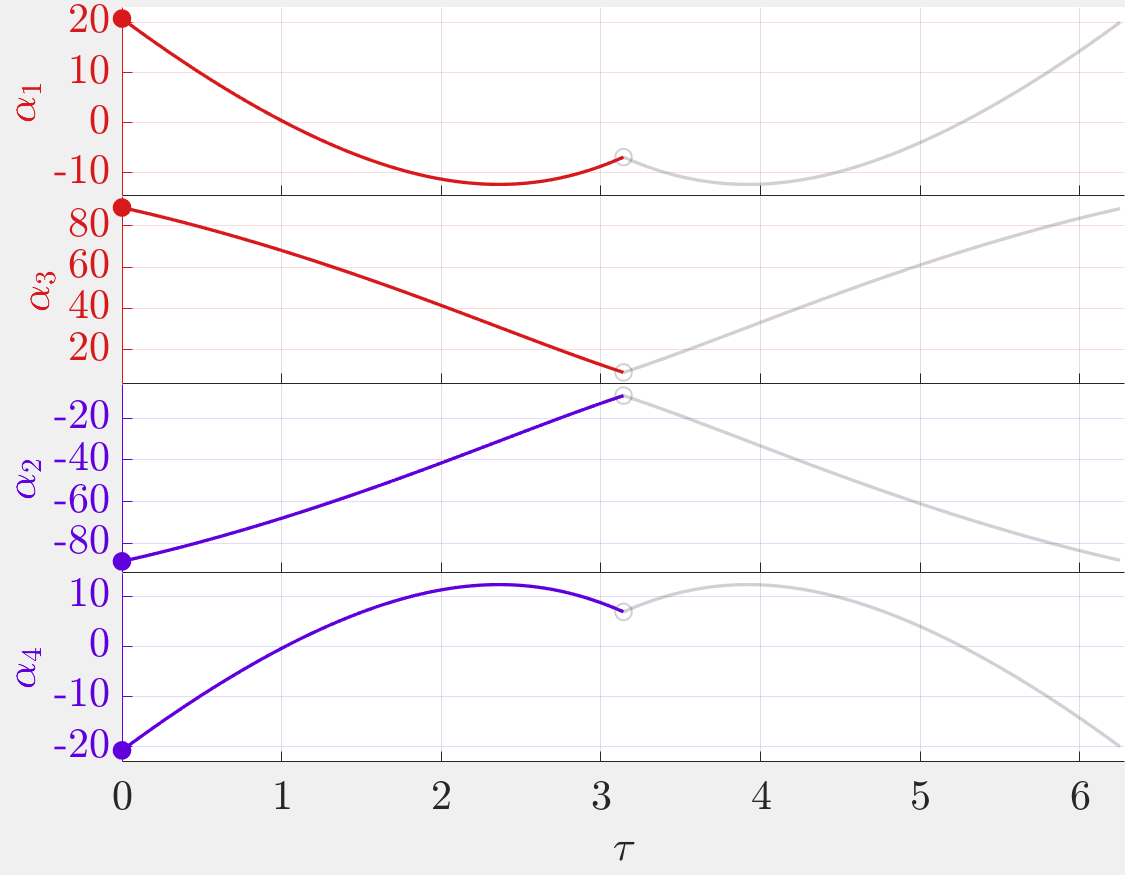

altQuadGait.plotShapeTimeseries(rigidTrot, ref13, ref24, inputs, pltStruct);

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
hamr6_F = false;
switch hamr6_F
    case true
        dataName = 'Data\HAMR6_SE2_kinematics.mat';
        dataMotPlanName = 'Data\HAMR6_SE2_kinematics_motionplan.mat';
        dataMobility = 'Data\HAMR6_SE2_kinematicMobility.mat';
    case false
        dataName = 'Data\case_1_kinematics.mat';
        dataMotPlanName = 'Data\case_1_kinematics_motionplan.mat';
        dataMobility = 'Data\case_1_kinematicMobility.mat';
end
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
if exist(dataName, "file")
    load(dataName);
else
    error(['ERROR! The base kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx".']);
end
if exist(dataMotPlanName, "file")
    load(dataMotPlanName);
else
    error(['ERROR! The motion planning kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx" (last section).']);
end
if exist(dataMobility, "file")
    load(dataMobility);
else
    error(['ERROR! The mobility kinematics data file is needed. ' ...
        'Create one in the first section of this livescript.']);
end

### Local connection and curvature in the stance space

The two leafs of the foliation in the shape subspaces induced by the squared-inter leg distance, $F$, form their own subspace over which paths along $x$ indicate stance phase paths during the first subgait and similarly, paths along $y$ indicate stance paths during the second subgait. Because the stratified panels, $dz$, or the connection vector fields in the stance space, $\mathbf{A}_{i} \text{ or } \mathbf{A}_{j}$, are conservative (nonslip constraint is holonomic and the current $F$ value is conserved), these individual paths in each direction can be combined in a path independent way from the initial point in each stance phase to the final point at the end of each stance phase.

Here, we obtain a description of the local connection in the stance space, its lie-bracket (local curvature form because the vector fields are conservative), and the dot product between the two vector field directions to discuss their span for gait controllability arguments.

The connection or stratified panels:

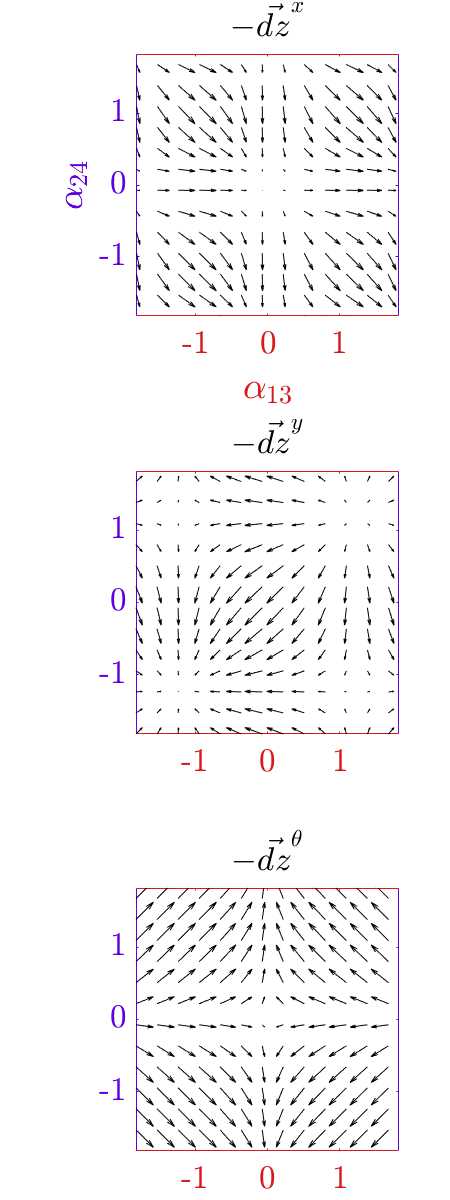

altQuadGait.plotStanceSpacePanels(rigidTrot);

The lie-bracket or the local curvature form ($\theta$-direction is ignored as it is uniformly zero):

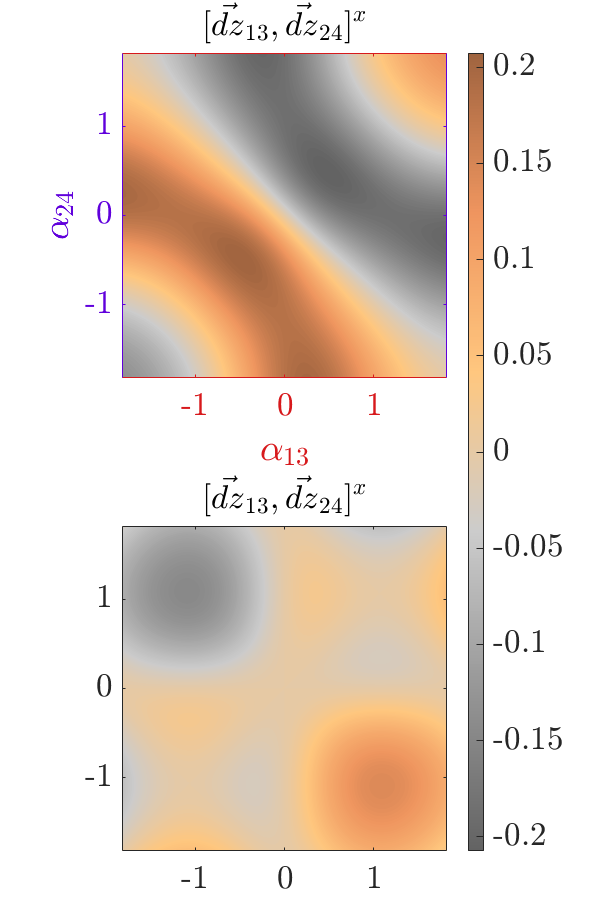

altQuadGait.plotStanceSpaceCurvature(rigidTrot);

The normalized dot product (span drops when the contours are either 1 or -1 when $dz_i$ or $dz_j$ are aligned):

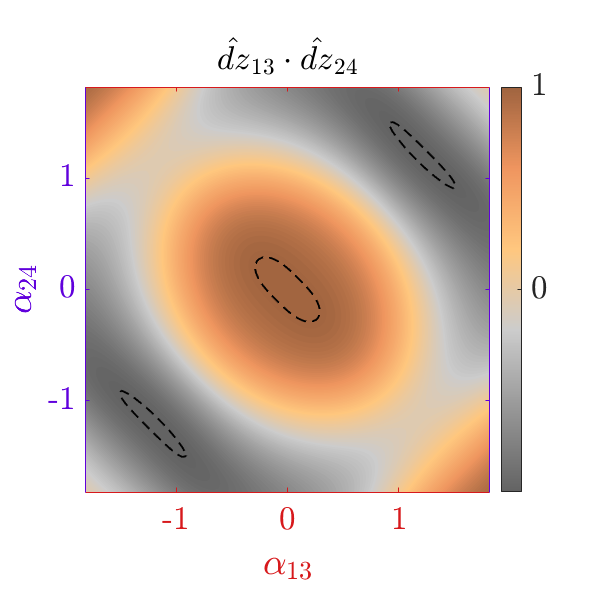

altQuadGait.plotStanceSpaceInterpanelDotProduct(rigidTrot);

This section is to help us visualize the stratified panels and the higher order lie-bracket corrections in the stance space.

FRHLstance.aParaRef
FLHRstance.aParaRef

Here's a quick and dirty way of visualizing the lie-bracket that encodes the noncommutativity.

t13 = FRHLstance.aParaRef.t; t24 = FLHRstance.aParaRef.t;
[t13, t24] = meshgrid(t13, t24); 
dz13 = interp1(FRHLstance.aParaRef.t, FRHLstance.aParaRef.dz, reshape(t13, [numel(t13), 1]), "pchip");
dz24 = interp1(FLHRstance.aParaRef.t, FLHRstance.aParaRef.dz, reshape(t24, [numel(t24), 1]), "pchip");

% reshaping componentwise and rewrite vars
temp13__x = reshape(dz13(:, 1), size(t13)); 
    temp13__y = reshape(dz13(:, 2), size(t13)); 
        temp13__th = reshape(dz13(:, 3), size(t13));
            dz13 = nan([size(t13), 3]);
            dz13(:, :, 1) = temp13__x; 
                dz13(:, :, 2) = temp13__y; 
                    dz13(:, :, 3) = temp13__th;
temp24__x = reshape(dz24(:, 1), size(t24)); 
    temp24__y = reshape(dz24(:, 2), size(t24)); 
        temp24__th = reshape(dz24(:, 3), size(t24));
            dz24 = nan([size(t13), 3]);
            dz24(:, :, 1) = temp24__x; 
                dz24(:, :, 2) = temp24__y; 
                    dz24(:, :, 3) = temp24__th;

Now, we have all the components we need to compute the first order (or even nth order lie-brackets). We shall only focus on the first-order for this stuff.

% compute the lie-brackets componentwise (has only x and y components)
dzLieB_13_14__x = dz13(:, :, 2).*dz24(:, :, 3) - dz24(:, :, 2).*dz13(:, :, 3); 
dzLieB_13_14__y = dz24(:, :, 1).*dz13(:, :, 3) - dz13(:, :, 1).*dz24(:, :, 3);

Some colors and plotting parameters are defined here.

% stratified panels plotting parameters
skipV = 7.5; % IN PERCENTAGE
itQ = 1:round(skipV/100*2*floor(dnum/2)):dnum; % indices where the arrows are plotted
lW_Vector = (1.0/10)*skipV;
% colormap
CUB = flipud([159.3750,99.6030,63.4312;
          239.0625,149.4045,95.1469;
          255.0000,199.2060,126.8625;
            204,204,204;
            150,150,150;
            99,99,99])/255;
CUB = interp1(linspace(0,100,size(CUB,1)), CUB, linspace(0,100,size(turbo,1)));
% color limits for the plot
lieColorLimits = [min([min(dzLieB_13_14__x, [], "all") min(dzLieB_13_14__y, [], "all")]),...
                  max([max(dzLieB_13_14__x, [], "all") max(dzLieB_13_14__y, [], "all")])]; 

First, we plot the stratified panels in this stance subspace. This also provides a perspective on the continuized system obtained by condensing each nonslip coordinate.

f = figure('units', 'pixels', 'position', [0 0 600 1200], 'Color','w'); set(f,'Visible','on');
tl = tiledlayout(f, 3, 1, "TileSpacing", "compact", "Padding", "tight");
% tlXY = tiledlayout(tl, 2, 1, "TileSpacing", "tight", "Padding", "tight"); tlXY.Layout.Tile = 1;
% tlYaw = tiledlayout(tl, 1, 1, "TileSpacing", "tight", "Padding", "tight"); tlYaw.Layout.Tile = 3;

dz13__x = reshape(dz13(:, :, 1), dnum, dnum);
    dz13__y = reshape(dz13(:, :, 2), dnum, dnum);
        dz13__yaw=reshape(dz13(:, :, 3), dnum, dnum);
dz24__x = reshape(dz24(:, :, 1), dnum, dnum);
    dz24__y = reshape(dz24(:, :, 2), dnum, dnum);
        dz24__yaw=reshape(dz24(:, :, 3), dnum, dnum);

ax = nexttile(tl); hold(ax, "on"); box(ax, "on"); ax.LineWidth = 1.2; % tlXY
quiver(ax, t13(itQ,itQ), t24(itQ,itQ), dz13__x(itQ,itQ), dz24__x(itQ,itQ),...
    'LineWidth', lW_Vector, 'Color', 'k');
xline(ax, 0, ':', LineWidth=0.5); yline(ax, 0, ':', LineWidth=0.5); 
xticks(ax, linspace(min(FRHLstance.aParaRef.t), max(FRHLstance.aParaRef.t), 3)); 
yticks(ax, linspace(min(FLHRstance.aParaRef.t), max(FLHRstance.aParaRef.t), 3));
ax.FontSize = 26.5; axis(ax, "equal", ...
    [min(FRHLstance.aParaRef.t) max(FRHLstance.aParaRef.t) ...
    min(FLHRstance.aParaRef.t) max(FLHRstance.aParaRef.t)]);
title(ax, '$$dz_{13 \leftrightarrow 24}^x$$', 'FontSize', 30);

ax = nexttile(tl); hold(ax, "on"); box(ax, "on"); ax.LineWidth = 1.2; % tlXY
quiver(ax, t13(itQ,itQ), t24(itQ,itQ), dz13__y(itQ,itQ), dz24__y(itQ,itQ),...
    'LineWidth', lW_Vector, 'Color', 'k');
xline(ax, 0, ':', LineWidth=0.5); yline(ax, 0, ':', LineWidth=0.5); 
xticks(ax, linspace(min(FRHLstance.aParaRef.t), max(FRHLstance.aParaRef.t), 3)); 
yticks(ax, linspace(min(FLHRstance.aParaRef.t), max(FLHRstance.aParaRef.t), 3));
ax.FontSize = 26.5; axis(ax, "equal", ...
    [min(FRHLstance.aParaRef.t) max(FRHLstance.aParaRef.t) ...
    min(FLHRstance.aParaRef.t) max(FLHRstance.aParaRef.t)]);
title(ax, '$$dz^y$$', 'FontSize', 30);

ax = nexttile(tl); hold(ax, "on"); box(ax, "on"); ax.LineWidth = 1.2; % tlYaw
quiver(ax, t13(itQ,itQ), t24(itQ,itQ), dz13__yaw(itQ,itQ), dz24__yaw(itQ,itQ),...
    'LineWidth', lW_Vector, 'Color', 'k');
xline(ax, 0, ':', LineWidth=0.5); yline(ax, 0, ':', LineWidth=0.5); 
xticks(ax, linspace(min(FRHLstance.aParaRef.t), max(FRHLstance.aParaRef.t), 3)); 
yticks(ax, linspace(min(FLHRstance.aParaRef.t), max(FLHRstance.aParaRef.t), 3));
ax.FontSize = 26.5; axis(ax, "equal", ...
    [min(FRHLstance.aParaRef.t) max(FRHLstance.aParaRef.t) ...
    min(FLHRstance.aParaRef.t) max(FLHRstance.aParaRef.t)]);
title(ax, '$$dz^{\theta}$$', 'FontSize', 30);

Plot just the lie-bracket scalar fields.

mul = 1.00;
f = figure('units', 'pixels', 'position', [0 0 750 1200], 'Color','w'); set(f,'Visible','on');
tl = tiledlayout(f, 2, 1, "TileSpacing", "compact", "Padding", "compact");

ax = nexttile(tl); hold(ax, "on"); box(ax, "on"); ax.LineWidth = 1.2;
contourf(ax, t13, t24, dzLieB_13_14__x, 100, 'LineStyle', 'none');
xline(0, ':', LineWidth=0.5); yline(0, ':', LineWidth=0.5); 
xticks(linspace(min(FRHLstance.aParaRef.t), max(FRHLstance.aParaRef.t), 3)); 
yticks(linspace(min(FLHRstance.aParaRef.t), max(FLHRstance.aParaRef.t), 3));
ax.FontSize = 26.5; clim(ax, mul*lieColorLimits); colormap(ax, CUB); axis(ax, "equal", "tight");
title(ax, '$$[dz_{13}, dz_{24}]^x$$', 'FontSize', 30);

ax = nexttile(tl); hold(ax, "on"); box(ax, "on"); ax.LineWidth = 1.2;
contourf(t13, t24, dzLieB_13_14__y, 100, 'LineStyle', 'none');
xline(0, ':', LineWidth=0.5); yline(0, ':', LineWidth=0.5);
xticks(linspace(min(FRHLstance.aParaRef.t), max(FRHLstance.aParaRef.t), 3)); 
yticks(linspace(min(FLHRstance.aParaRef.t), max(FLHRstance.aParaRef.t), 3));
ax.FontSize = 26.5; clim(ax, mul*lieColorLimits); colormap(ax, CUB); axis(ax, "equal", "tight");
title(ax, '$$[dz_{13}, dz_{24}]^y$$', 'FontSize', 30);

cBar = colorbar(); cBar.Layout.Tile = 'East'; cBar.TickLabelInterpreter = 'latex'; cBar.FontSize = 26.5;

Package data into some structs before saving the resuts. Makes the workspace more concise.

bodyF = []; % create the body trajectory
bodyF.stanceTraj.i = g13; bodyF.stanceTraj.j = g24;
bodyF.stanceDisp.i = z24; bodyF.stanceDisp.j = z24;
bodyF.totalTraj = gb; bodyF.totalDisp = zb;
stanceSpace = []; % create the stance space
stanceSpace.coords{1} = t13; stanceSpace.coords{2} = t24; % ... get the coords
stanceSpace.panels{1} = dz13; stanceSpace.panels{2} = dz24; % ... get the panels
stanceSpace.lieBrackets = cat(3, dzLieB_13_14__x, dzLieB_13_14__y); % ... get the first order lie-brackets
stanceSpace.lieBrackets(:, :, end+1) = ... % ... ... append zeros for the theta direction
    zeros(size(stanceSpace.lieBrackets, 1), size(stanceSpace.lieBrackets, 2));

Save the results.

if exist(dataMobility, "file")
    save(...
        dataMobility, ...
    "ref13", "ref24", "inputs", ...
    "FRHLstance", "FLHRstance", ...
    "configTraj13", "configTraj24", ...
    "jointStancePath", ...
    "bodyF", ...
    "stanceSpace", ...
    "-append"...
        );
else
    error(['ERROR! The mobility kinematics data file is needed. ' ...
        'Create one in the first section of this livescript.']);
end